% AAE 666 HW4 Exercise-4
% Tomoki Koike
close all; clear all; clc;
fdir = 'C:\Users\Tomo\Desktop\studies\2021-Spring\AAE666\matlab\hw4';
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');

% Constants
k1 = 1.25;
k2 = 1.5;

% Generate random ones
low  = -3;
high = 3;
rgen = @(a,b) (b-a).*rand(5,1) + a;

x1_0s = rgen(low, high);
x2_0s = rgen(low, high);
x1_0s = [0.1; x1_0s];
x2_0s = [0.1; x2_0s];

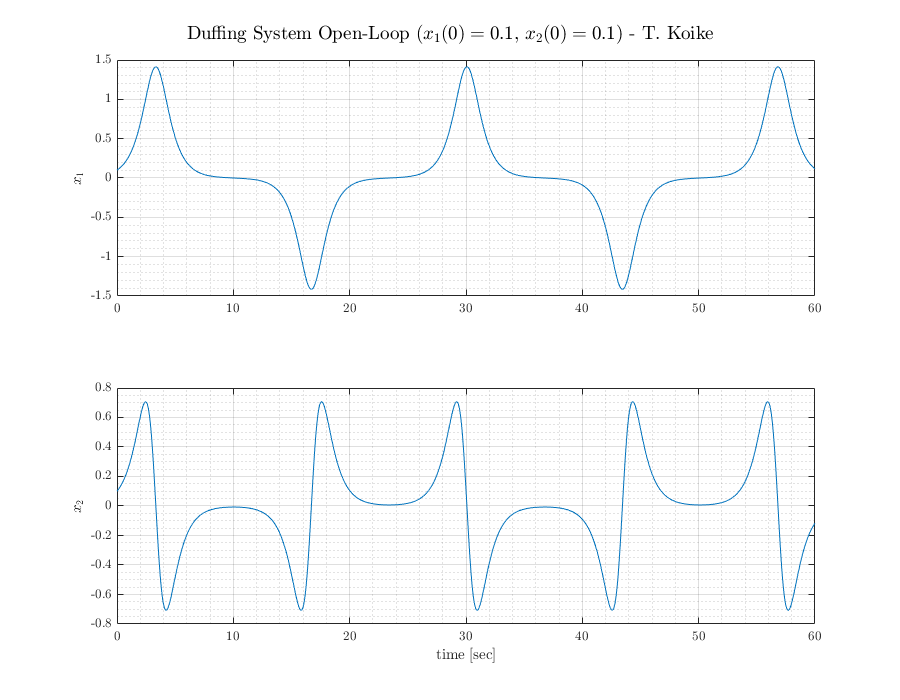

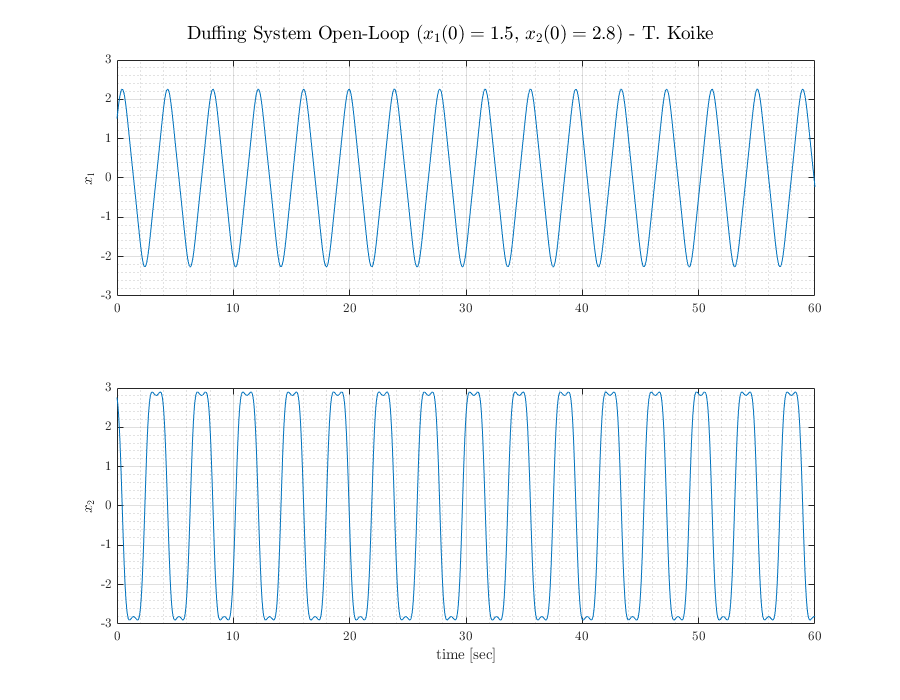

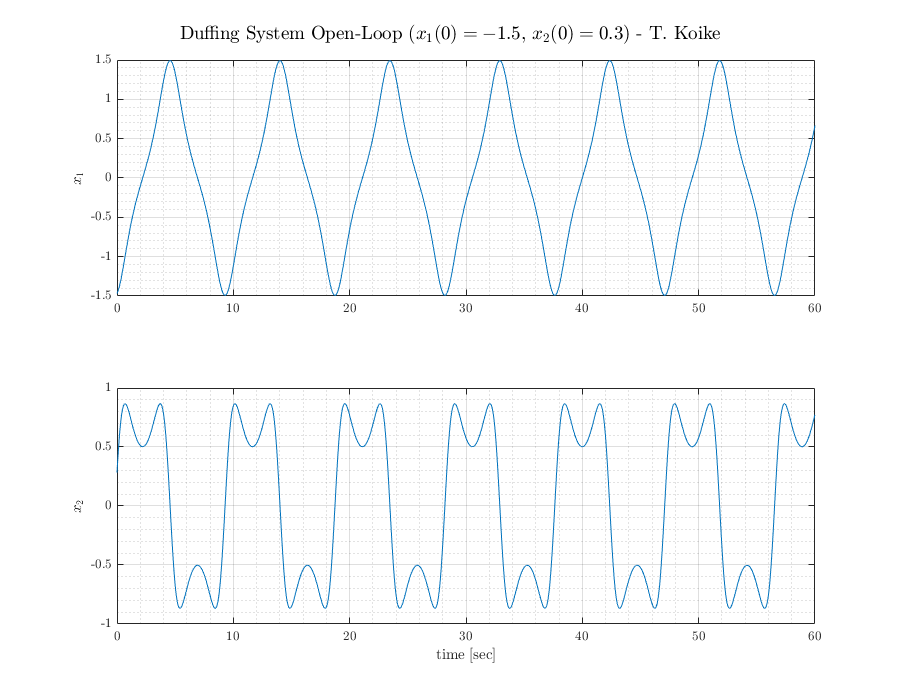

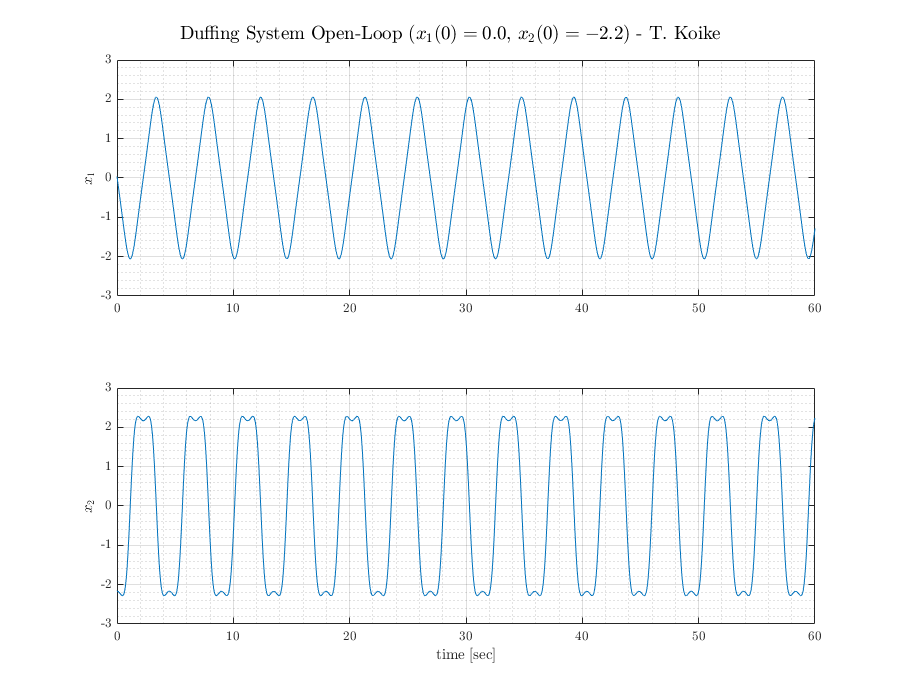

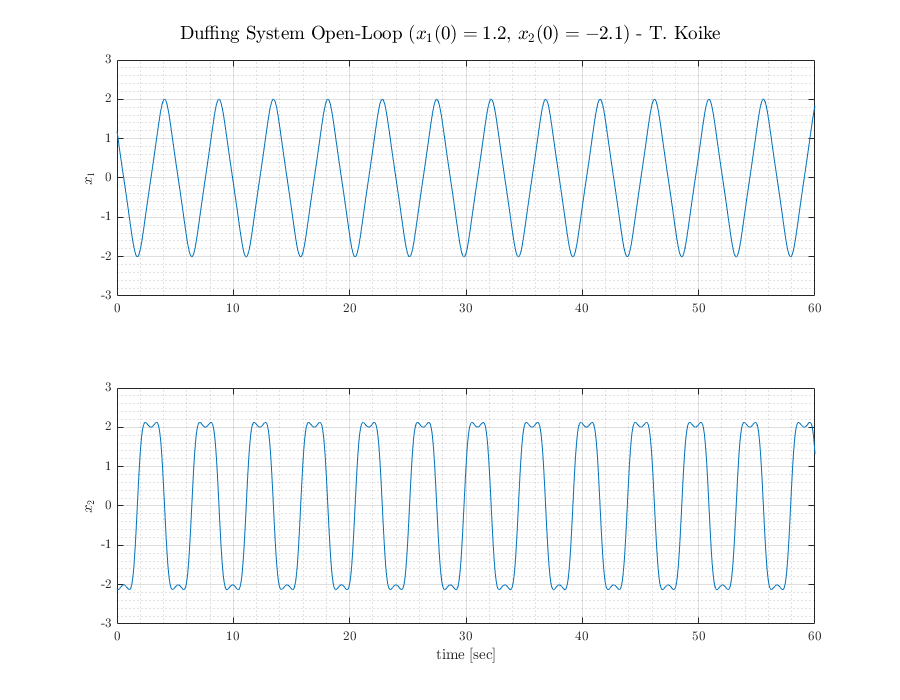

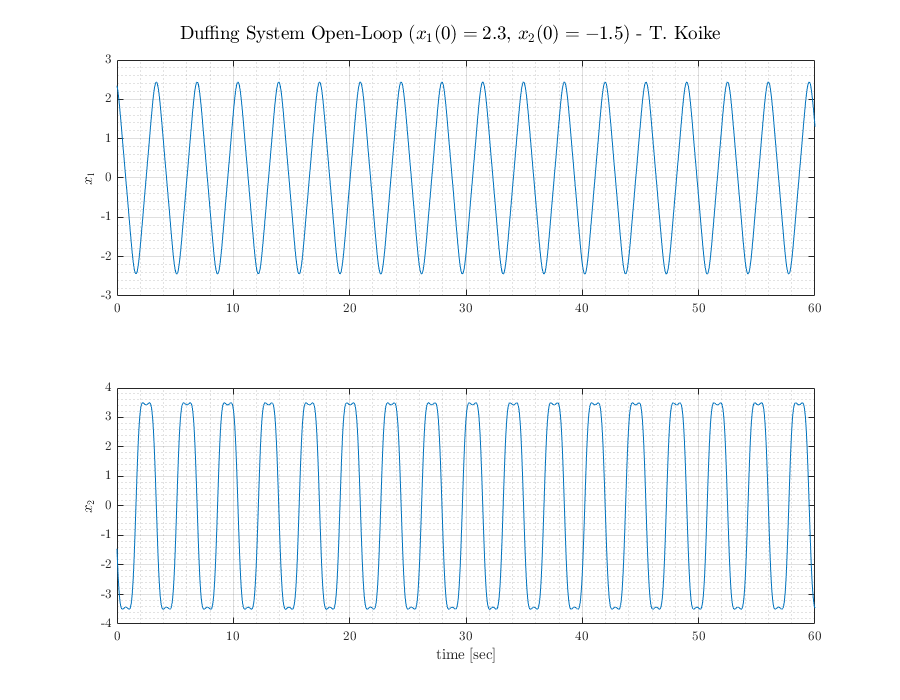

% Open Loop Simulation
% - Set flag to switch SIMULINK to open loop
flag = -1;

for i = 1:length(x1_0s)
    x1_0 = x1_0s(i);
    x2_0 = x2_0s(i);
    
    % - Simulate 
    simout = sim("duffingSystem.slx");
    
    % - Data rendering 
    x1 = simout.x1sim.signals.values;
    x2 = simout.x2sim.signals.values;
    t  = simout.tout;
    
    % - Plot 
    fig = figure("Renderer","painters","Position",[60 60 900 700]);
        subplot(2,1,1)
        plot(t, x1)
        grid on; grid minor; box on;
        ylabel('$x_1$')
        subplot(2,1,2)
        plot(t, x2)
        grid on; grid minor; box on;
        ylabel('$x_2$')
        xlabel('time [sec]')
        title_string = 'Duffing System Open-Loop ($x_1(0)=%0.1f$, $x_2(0)=%0.1f$) - T. Koike';
        title_S = sprintf(title_string, x1_0, x2_0);
        sgtitle(title_S)
    file_string = 'hw4_ex4_OL_case%d.png';
    file_S = sprintf(file_string, i);
    saveas(fig, file_S);
end

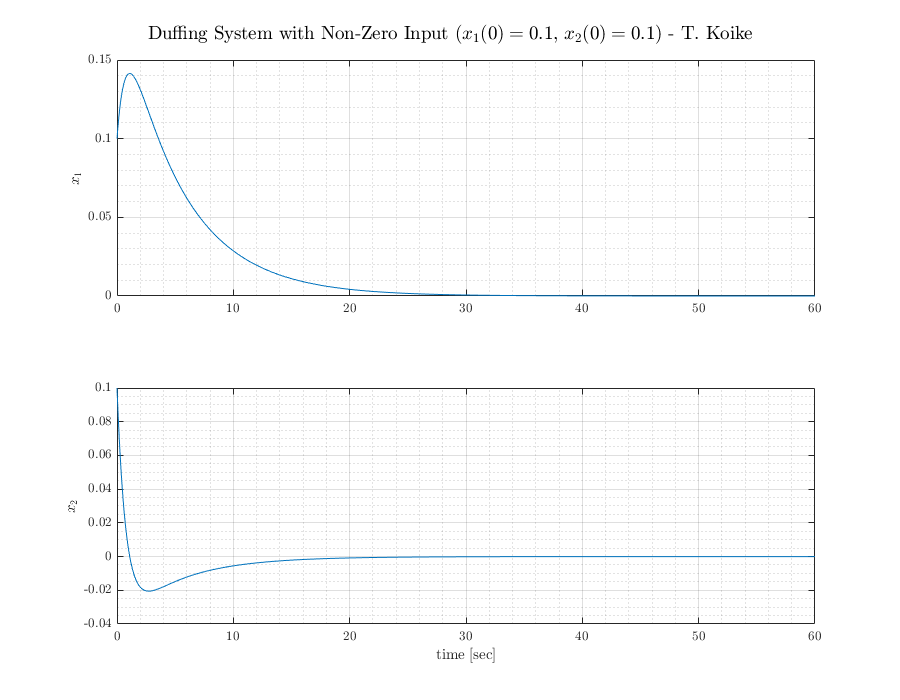

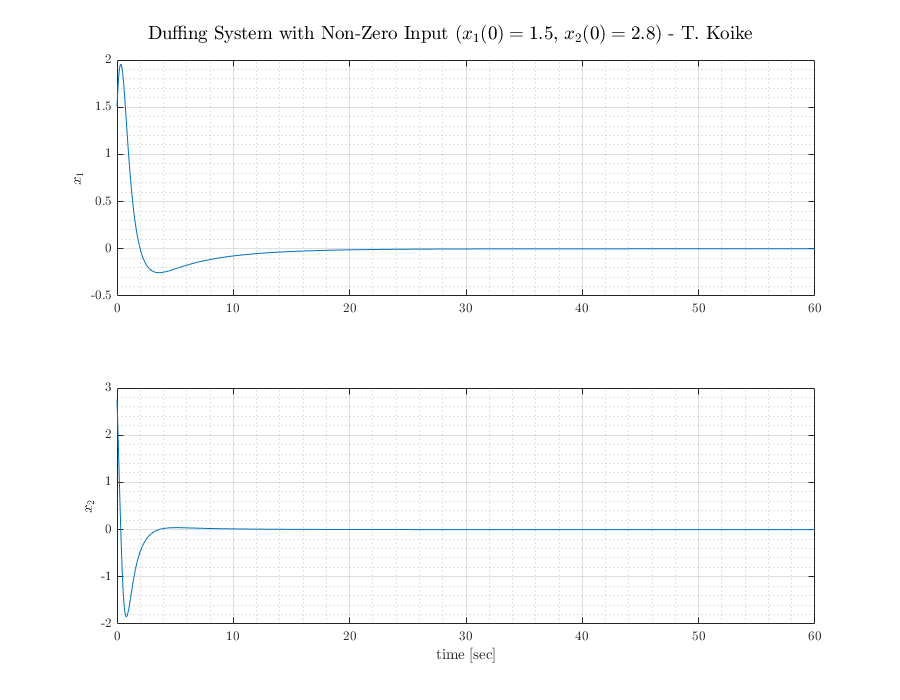

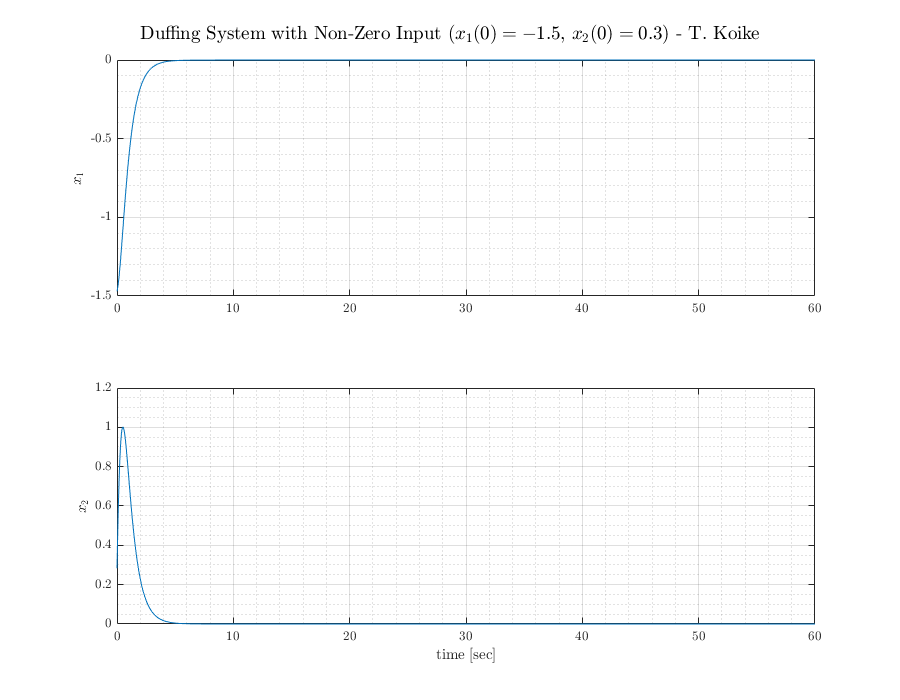

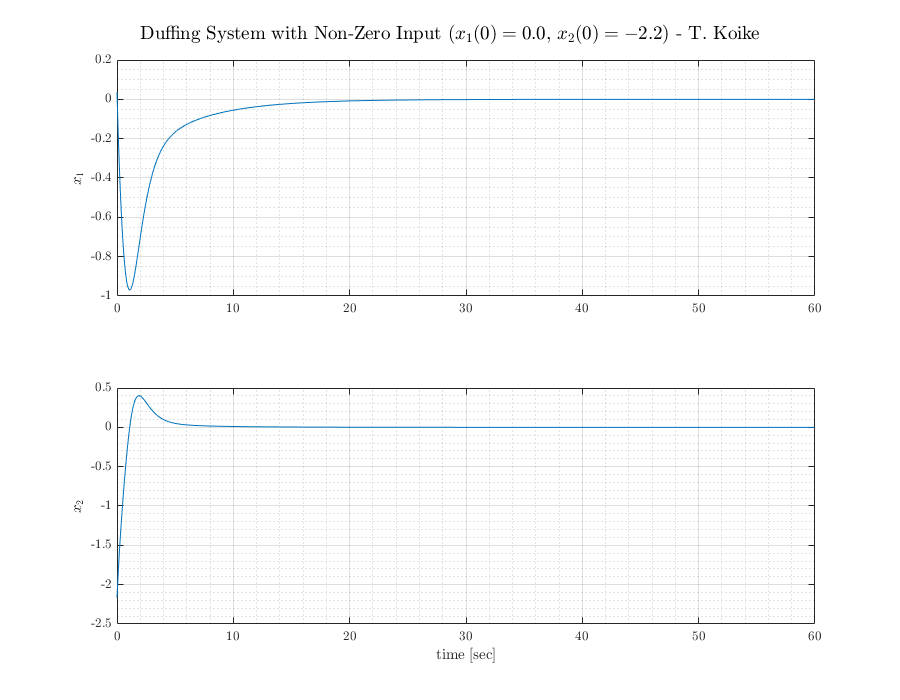

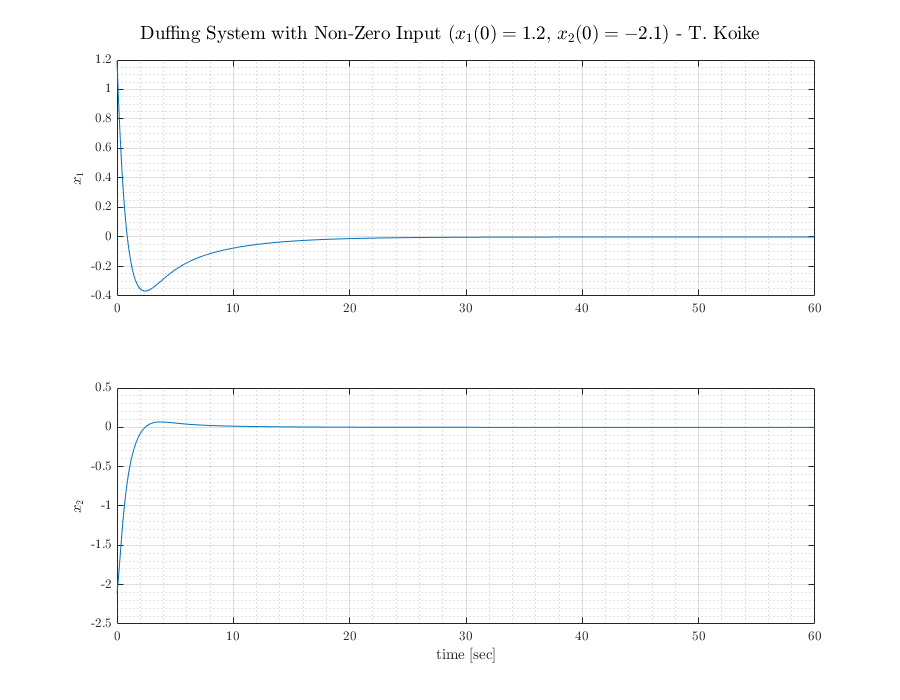

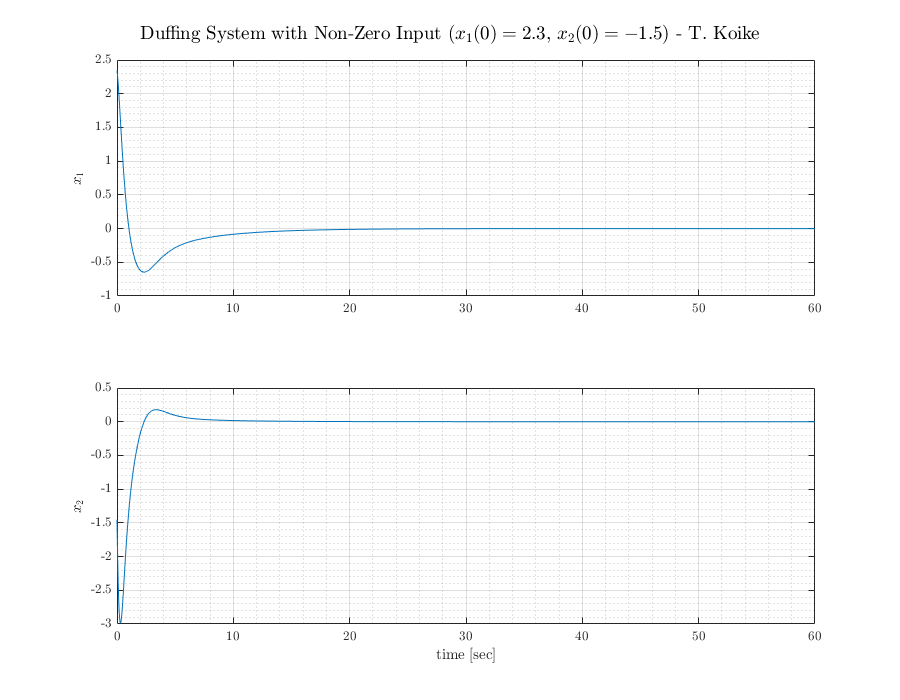

% Closed Loop Simulation
% - Set flag to switch SIMULINK to open loop
flag = 1;

for i = 1:length(x1_0s)
    x1_0 = x1_0s(i);
    x2_0 = x2_0s(i);
    
    % - Simulate 
    simout = sim("duffingSystem.slx");
    
    % - Data rendering 
    x1 = simout.x1sim.signals.values;
    x2 = simout.x2sim.signals.values;
    t  = simout.tout;
    
    % - Plot 
    fig = figure("Renderer","painters","Position",[60 60 900 700]);
        subplot(2,1,1)
        plot(t, x1)
        grid on; grid minor; box on;
        ylabel('$x_1$')
        subplot(2,1,2)
        plot(t, x2)
        grid on; grid minor; box on;
        ylabel('$x_2$')
        xlabel('time [sec]')
        title_string = 'Duffing System with Non-Zero Input ($x_1(0)=%0.1f$, $x_2(0)=%0.1f$) - T. Koike';
        title_S = sprintf(title_string, x1_0, x2_0);
        sgtitle(title_S)
    file_string = 'hw4_ex4_CL_case%d.png';
    file_S = sprintf(file_string, i);
    saveas(fig, file_S);
end